## Analysis Dataset 1: Evoked Response Potential (ERP) of affective picture (IAPS)

The following script shows how dataset 1 was analyzed using the time-GAL toolbox. EEG data can be retrieved from the OSF repository (https://osf.io/q56ns/) and found in folder "Dataset1_IAPS_ERP".

#### Import/group data

The time-GAL toolbox needs data to be formated in a specific way: One 3D (matrix channels, time, trials) and one vector indicating subject's id of each trial. These matrix and vector are needed for each condition. Here, we show the example with pleasant vs. unpleasant figures:

[Data_Condition_Pleasant, List_Condition_Pleasant] = groupCondition('./Dataset1_IAPS_ERP/', 'Data_Pleasant', 'Data', 'FileName', 'Condition_Pleasant');


 
 A total of 39 files were found with tag: Data_Pleasant    Data: [129×601×32 double]


 Reading file: Data_Pleasant_subject_1.mat | File 1 out of 39
 Reading file: Data_Pleasant_subject_10.mat | File 2 out of 39
 Reading file: Data_Pleasant_subject_11.mat | File 3 out of 39
 Reading file: Data_Pleasant_subject_12.mat | File 4 out of 39
 Reading file: Data_Pleasant_subject_13.mat | File 5 out of 39
 Reading file: Data_Pleasant_subject_14.mat | File 6 out of 39
 Reading file: Data_Pleasant_subject_15.mat | File 7 out of 39
 Reading file: Data_Pleasant_subject_16.mat | File 8 out of 39
 Reading file: Data_Pleasant_subject_17.mat | File 9 out of 39
 Reading file: Data_Pleasant_subject_18.mat | File 10 out of 39
 Reading file: Data_Pleasant_subject_19.mat | File 11 out of 39
 Reading file: Data_Pleasant_subject_2.mat | File 12 out of 39
 Reading file: Data_Pleasant_subject_20.mat | File 13 out of 39
 Reading file: Data_Pleasant_subject_21.mat | File 14 out of 39
 Reading file: Data_Pleas

[Data_Condition_Unpleasant, List_Condition_Unpleasant] = groupCondition('./Dataset1_IAPS_ERP/', 'Data_Unpleasant', 'Data', 'FileName', 'Condition_Unpleasant');


 
 A total of 39 files were found with tag: Data_Unpleasant    Data: [129×601×26 double]


 Reading file: Data_Unpleasant_subject_1.mat | File 1 out of 39
 Reading file: Data_Unpleasant_subject_10.mat | File 2 out of 39
 Reading file: Data_Unpleasant_subject_11.mat | File 3 out of 39
 Reading file: Data_Unpleasant_subject_12.mat | File 4 out of 39
 Reading file: Data_Unpleasant_subject_13.mat | File 5 out of 39
 Reading file: Data_Unpleasant_subject_14.mat | File 6 out of 39
 Reading file: Data_Unpleasant_subject_15.mat | File 7 out of 39
 Reading file: Data_Unpleasant_subject_16.mat | File 8 out of 39
 Reading file: Data_Unpleasant_subject_17.mat | File 9 out of 39
 Reading file: Data_Unpleasant_subject_18.mat | File 10 out of 39
 Reading file: Data_Unpleasant_subject_19.mat | File 11 out of 39
 Reading file: Data_Unpleasant_subject_2.mat | File 12 out of 39
 Reading file: Data_Unpleasant_subject_20.mat | File 13 out of 39
 Reading file: Data_Unpleasant_subject_21.mat | File 14 out o

Once grouped all data from the folder of subject's files in two conditions data, it is saved on a file and workspace. We can use either the workspace data or load it again in a new session:

% load('Condition_Pleasant.mat');
% load('Condition_Unpleasant.mat');

#### Computing time-GAL method

Now, data is ready to be included in the toolbox as input. We use the time-GAL toolbox to compare Pleasant vs. Unpleasant EEG responses. To speed-up the MVPA decoding process, we takes advantage of the parallel computing toolbox implemented in MATLAB by using parameters 'ParallelComputing', true and 'ParallelComputingCores', 4. Since 4 channels are facials and we disregard this information, we use the parameter 'Channels' to select the EEG sensors to be used in the analysis. Finally, results are saved in a mat file.

[timeGALoutput] = timeGAL(Data_Condition_Pleasant, Data_Condition_Unpleasant, List_Condition_Pleasant, List_Condition_Unpleasant, ...
    'ParallelComputing', true, 'ParallelComputingCores', 4, ...
    'Channels', [1:124 129], ...
    'Filename', 'resultsTimeGAL_IAPS_ERP.mat')


 1. Initializing function. 

 Using Parallel Computing Toolbox with 4 cores 

Starting parallel pool (parpool) using the 'LocalProfile4cores' profile ...
Preserving jobs with IDs: 4 5 6 7 19 25 26 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile LocalProfile4cores. To create 'myCluster' use 'myCluster = parcluster('LocalProfile4cores')'.
Connected to parallel pool with 4 workers.

 
 2. Computing GAL matrices. Progress:

 Subject: 1 | 1 out of 39  

 Subject: 2 | 2 out of 39  

 Subject: 4 | 4 out of 39  

 Subject: 3 | 3 out of 39  
.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|
 Time elapse: 1 minutes 1.333896e+01 seconds
 Subject: 8 | 8 out of 39  
.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|.|

timeGALoutput = struct with fields:
    GeneralizationMatrix: [1×1 struct]
       CorrelationMatrix: [1×1 struct]
                 TimeGAL: [1×1 struct]
              Parameters: [1×1 struct]


Once decoding calculations has been computed, results can be found in the variable timeGALoutput both in the workspace and the mat file. We can load it if needed in a different session:

% load('resultsTimeGAL_IAPS_ERP.mat')

#### Visualization of results

Finally, once time-GAL has been calculated, we can explore the results by visualizing them. All the important data such as GAL, correlation and time-GAL matrices can be found in the timeGALoutput variable (i.e. the file if it was saved). While visualization can be independently crafted by the user, the time-GAL toolbox provides its own function for easiness and convenience. It contains a few parameters to change statistical alpha thresholds, titles, file saving or resolutions, for example. However, for simplicity, here we only use the function fed with the time-GAL output:

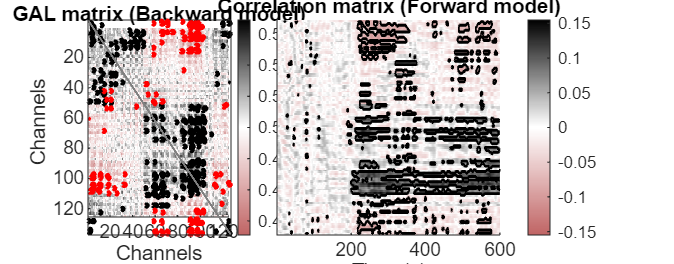

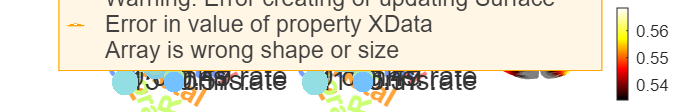

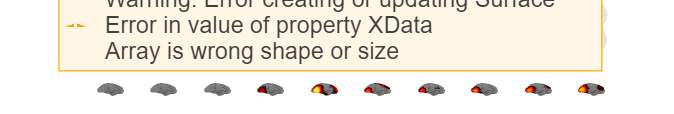

visualizationTimeGAL(timeGALoutput)

This function plots three figures showing (1) the GAL and correlation matrices, (2) the circular connectivity plots and topography, and (3) the time-GAL and topography across the trial.